%% REFERENCE
% Consensus Equilibrium for Super-Resolution and Extreme-Scale CT SC %19, November 17–22, 2019, Denver, CO, USA


%% CE-MBIR Equation
% Algorithm 2 Consensus Equilibrium MBIR
% INPUT: Measurements y and matrix A partitioned in any order.
% LOCAL: wi : a temporary copy for vi . ui : input change to proximal
% map function, Fi (x). Other variables are the same as in
% Algorithm 1.
% OUTPUT: x: the consensus HR solution.
% 1: Initialize x, vi , wi , and ui
% 2: while x , vi , i = 1, 2, ...,G do
% 3: for each subset i from 1 to G do in parallel
% 4: vi ← argminvi Fi (x + ui )
% 5: (w′)i ←wi
% 6: wi ← (2vi − x − ui )
% 7: wi ← ρwi +􀀀1 − ρ�(w′)i , 0 ≤ ρ ≤ 1
% 8: end for
% 9: x ← Average(w1, · · · ,wG)
% 10: for each subset i from 1 to G do in parallel
% 11: ui ←x − wi
% 12: end for
% 13: end while

%% 


clear ;

isgpu   = true;


addpath(genpath('./utilities/'));
addpath(genpath('./denoisers/'));
% addpath(genpath('D:\software\MATLAB\R2021a\toolbox\astra-1.9.0.dev11-matlab-win-x64'));
addpath(genpath('D:\software\MATLAB\R2021a\toolbox\TIGRE_toolbox\TIGRE-master'));
addpath(genpath('D:\FILE\SPC_demos\BM3D\BM4D-master'));

%% SYSTEM SETTING

N       = 128;
% ANG     = 180;
ANG     = pi;           % Angle range 0-180

G       = 2;            % Number of subsets
VIEW_F    = 360;        % Number of subsets
VIEW    = 360/G;
THETA   = zeros(G,VIEW);
Offset  = zeros(1,G);

THETA_F   = linspace(0, ANG, VIEW_F + 1);   THETA_F(end) = [];

A       = cell(1,G);        
AT      = cell(1,G);
AINV    = cell(1,G);


%% DATA GENERATION

%% Define Geometry
% 
% VARIABLE                                   DESCRIPTION                    UNITS
%-------------------------------------------------------------------------------------
geo.DSD = 4000;                             % Distance Source Detector      (mm)
geo.DSO = 2000;                             % Distance Source Origin        (mm)
% Detector parameters

% Make the pixels in the detector the same size as the image voxels
% (or viceversa)!

geo.nDetector=[128; 128];					% number of pixels              (px)
geo.dDetector=[5.5; 5.5]; 					% size of each pixel            (mm)
geo.sDetector=geo.nDetector.*geo.dDetector; % total size of the detector    (mm)
% Image parameters
geo.nVoxel=[128;128;128];                   % number of voxels              (vx)
geo.dVoxel=[4;4;4];                         % size of each voxel            (mm)
geo.sVoxel=geo.nVoxel.*geo.dVoxel;          % total size of the image       (mm)
% Offsets
geo.offOrigin =[0;0;0];                     % Offset of image from origin   (mm)              
geo.offDetector=[0;0];                     % Offset of Detector            (mm)
% Auxiliary 
geo.accuracy=0.5;                           % Accuracy of FWD proj          (vx/sample)


%% As easy as this:
geo.mode='parallel';
% geo.mode='cone';
head=headPhantom(geo.nVoxel);


% %--------------------------------------------------------------------------------
% 
% geo.DSD = 4000;                             % Distance Source Detector      (mm)
% geo.DSO = 2000;                             % Distance Source Origin        (mm)
% % Detector parameters
% 
% % Make the pixels in the detector the same size as the image voxels
% % (or viceversa)!
% 
% geo.nDetector=[512; 512];					% number of pixels              (px)
% geo.dDetector=[5.5; 5.5]; 					% size of each pixel            (mm)
% geo.sDetector=geo.nDetector.*geo.dDetector; % total size of the detector    (mm)
% % Image parameters
% geo.nVoxel=[512;512;318];                   % number of voxels              (vx)
% geo.dVoxel=[4;4;4];                         % size of each voxel            (mm)
% geo.sVoxel=geo.nVoxel.*geo.dVoxel;          % total size of the image       (mm)
% % Offsets
% geo.offOrigin =[0;0;0];                     % Offset of image from origin   (mm)              
% geo.offDetector=[0; 0];                     % Offset of Detector            (mm)
% % Auxiliary 
% geo.accuracy=0.5;                           % Accuracy of FWD proj          (vx/sample)
% 
% 
% %% As easy as this:
% geo.mode='parallel';
% % geo.mode='cone';
% % head=headPhantom(geo.nVoxel);

A_F       = @(x) Ax(x, geo, THETA_F);
% AT_F      = @(y) iradon(y, THETA_F, 'none', N)/(pi/(2*length(THETA)));
AINV_F    = @(y) FDK(y, geo, THETA_F);

% denoiser= @wrapper_TV;
denoiser= @(image,sigma) im3DDenoise(image,'TV',1,sigma);
% denoiser= @(image,sigma) bm4d(image,'Rice',sigma);

for i = 1 : G
    
    Offset(i)   = (i-1)* (ANG/G/VIEW);      % View subsets
    THETA(i,:)  = linspace(0 + Offset(i), ANG - ANG/VIEW + Offset(i), VIEW);  % THETA(i,end) = [];
%     
%     Offset(i)   = (i-1)* (ANG/G);
%     THETA(i,:)  = linspace(0 + Offset(i), ANG/G + Offset(i), VIEW);  % THETA(i,end) = [];
    A{i}        = @(x) Ax(x, geo, THETA(i,:));      % Partition of system matrix A operator
    AT{i}       = @(y) FDK(y, geo, THETA(i,:))/(pi/(2*length(THETA(i,:))));
    AINV{i}     = @(y) FDK(y, geo, THETA(i,:));

end



% load('XCAT512.mat');
% load('Head_3d_256.mat'); % C_3d
% load('Chest_3d_512.mat'); % C_3d


% x       = imresize3(double(head), size(head));
x = head;
% x = C_3d;

p       = cell(1,G);
pn      = cell(1,G);
y       = cell(1,G);
v       = cell(1,G);
% v       = cell(1,G);

p_F     = A_F(x);
x_full  = AINV_F(p_F);


pn_F       = addCTnoise(p_F);
i0          = 6e5;                  % Set Poisson noise scaling factor
y_F         = pn_F;
v_F         = AINV_F(y_F);

    
for i = 1 : G

    p{i}        = A{i}(x);
    % x_full    = AINV(p);
    
    %% LOW-DOSE SINOGRAM GENERATION
    
%     pn{i}       = exp(-p{i});
%     pn{i}       = i0.*pn{i};
%     pn{i}       = poissrnd(pn{i});
%     pn{i}       = max(-log(max(pn{i},1)./i0),0);
    
    pn{i}       = addCTnoise(p{i},'Poisson',i0,'Gaussian',[0 10]);  % Add Poisson and Gaussian noise
    y{i}        = pn{i};
    
    %% Statistical Reconstruction Technique INITIALIZATION
    v{i}        = AINV{i}(y{i});


end


x0          = v{i};         % Set initial state of reconstruction
alpha      = 0.5;           % Set Gradent descent step size
niter       = 2e1;          % Set iteration number
bpos        = true;         % Non-nagetiveness
lambda       = 1/sqrt(i0);  % Set denoiser parameter
sigma2      = 5*G;          % Set proximal function scaling factor
rho         = 0.9;          % Set Mann update parameter

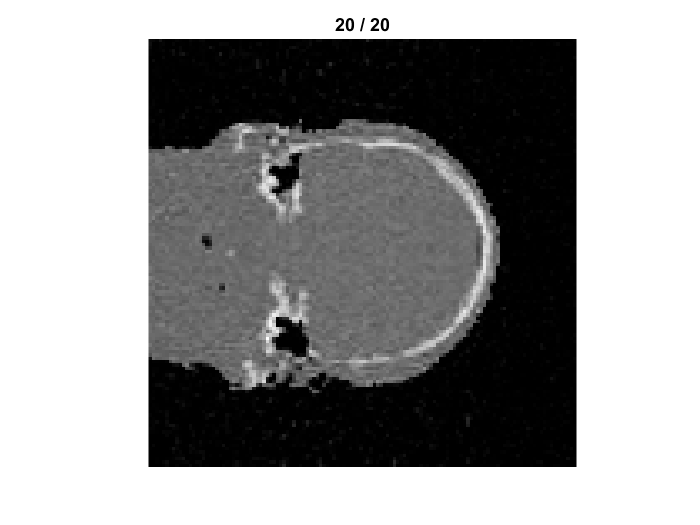

%% RUN Statistical Reconstruction Technique 

% if isgpu
%     y{i} = gpuArray(y{i});
%     x0 = gpuArray(x0);
% end

 tic
 
[x_art, x_art_stack]  = CE_MBIR_3d(A,AT,y,x0,G,denoiser,lambda,alpha,sigma2,rho,niter,bpos);        % Implement the reconstruction algorithm 3d

t3 = toc

t3 = 88.5581

%% CALCULATE QUANTIFICATION FACTOR


x_low       = max(v_F, 0);
x_art       = max(x_art, 0);
nor         = max(x(:));

mse_x_low   = immse(x_low./nor, x./nor);
mse_x_art   = immse(x_art./nor, x./nor);

psnr_x_low  = psnr(x_low./nor, x./nor);
psnr_x_art  = psnr(x_art./nor, x./nor);

ssim_x_low  = ssim(x_low./nor, x./nor);
ssim_x_art  = ssim(x_art./nor, x./nor);


%% DISPLAY
wndImg  = [0, 0.03];
wndPrj  = [0, 6];

figure(1);
colormap(gray(256));

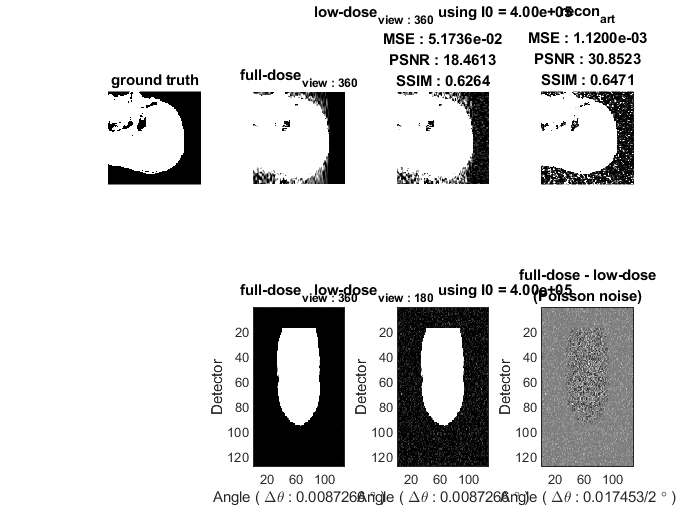

x_slide(:,:) = x(round(end/2),:,:);
x_full_slide(:,:) = x_full(round(end/2),:,:);
v_F_slide(:,:) = v_F(round(end/2),:,:);
x_art_slide(:,:) = x_art(round(end/2),:,:);
% x_slide(:,:) = x(:,round(end/2),:);
% x_full_slide(:,:) = x_full(:,round(end/2),:);
% v_F_slide(:,:) = v_F(:,round(end/2),:);
% x_art_slide(:,:) = x_art(:,round(end/2),:);

% suptitle('Algebraic Reconstruction Technique');
subplot(241);   imagesc(x_slide,      wndImg);    axis image off;     title(['ground truth']);

subplot(242);   imagesc(x_full_slide, wndImg);    axis image off;     title(['full-dose_{view : ', num2str(VIEW_F) '}']);
subplot(246);   imagesc(p_F(:,:,round(end/2)), wndPrj);         xlabel(['Angle ( \Delta\theta : ' num2str(ANG/VIEW_F) ' \circ )']);   ylabel('Detector'); title(['full-dose_{view : ', num2str(VIEW_F) '}']);

subplot(243);   imagesc(v_F_slide,  wndImg);    axis image off;     title({['low-dose_{view : ', num2str(VIEW_F) '}' ' using I0 = ' num2str(i0, '%.2e') ], ['MSE : ' num2str(mse_x_low, '%.4e')], ['PSNR : ' num2str(psnr_x_low, '%.4f')], ['SSIM : ' num2str(ssim_x_low, '%.4f')]});
subplot(247);   imagesc(y_F(:,:,round(end/2)),  wndPrj);        xlabel(['Angle ( \Delta\theta : ' num2str(ANG/VIEW_F) ' \circ )']);   ylabel('Detector'); title(['low-dose_{view : ', num2str(VIEW) '} using I0 = ' num2str(i0, '%.2e')]);

subplot(244);   imagesc(x_art_slide,  wndImg);    axis image off;     title({['recon_{art}'], ['MSE : ' num2str(mse_x_art, '%.4e')], ['PSNR : ' num2str(psnr_x_art, '%.4f')], ['SSIM : ' num2str(ssim_x_art, '%.4f')]});
subplot(248);   imagesc(y_F(:,:,round(end/2)) - p_F(:,:,round(end/2)));             xlabel( [ 'Angle ( \Delta\theta : ' num2str(ANG/VIEW) '/' num2str(G)  ' \circ )' ] );   ylabel('Detector'); title({['full-dose - low-dose'],'(Poisson noise)'});